% Setup
format compact
clearvars
clc

%Variables
TFG_Preload()
entradaString = '3V Pos - ';
Kp = 2; % 728/275;
Ki = 0; % 678/55;
Kd = 0; % 43/495;

%Parametres
OL2V = load('VelObert2v.mat');
OL2V = OL2V.simout;
VF2V = mean(OL2V(2500:3000,2));
Km2V = VF2V/(2*Ktac)

Km2V = single
45.1023

Val632V = VF2V*0.63

Val632V = single
0.7604

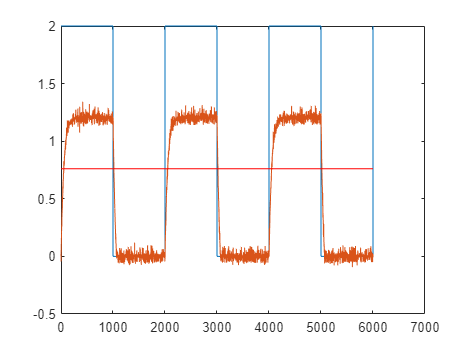

figure();
plot(OL2V(:,1:2),'DisplayName','OL2V');
hold on;
plot([0 length(OL2V)-1], [Val632V Val632V], 'r-');

tau2V = (2051-2000)*30/6000 % 30/6000 segons/mostra

tau2V = 0.2550


OL3V = load('VelObert3v.mat');
OL3V = OL3V.simout;
VF3V = mean(OL3V(2500:3000,2));
Km3V = VF3V/(3*Ktac)

Km3V = single
49.0555

Val633V = VF3V*0.63

Val633V = single
1.2405

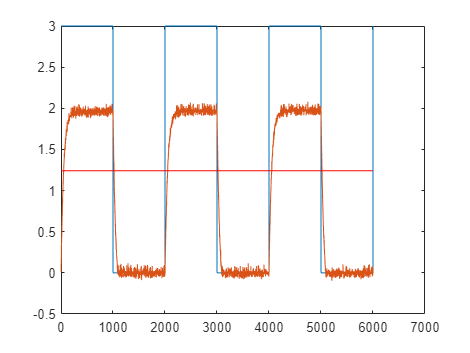

figure();
plot(OL3V(:,1:2),'DisplayName','OL3V');
hold on;
plot([0 length(OL3V)-1], [Val633V Val633V], 'r-');

tau3V = (2051-2000)*30/6000 % 30/6000 segons/mostra

tau3V = 0.2550

## Teoria

%F.T.
G = tf([K*Kpot*Kd K*Kpot*Kp K*Kpot*Ki], [9*tau 9+K*Kpot*Kd K*Kpot*Kp K*Kpot*Ki])

G =
 
            168.8 s
  ---------------------------
  2.295 s^3 + 9 s^2 + 168.8 s
 
Continuous-time transfer function.



dcgain(G)

ans = 1

zpk(G)

ans =
 
          73.551 s
  ------------------------
  s (s^2 + 3.922s + 73.55)
 
Continuous-time zero/pole/gain model.



pole(G)

ans =    0.0000 + 0.0000i
  -1.9608 + 8.3490i
  -1.9608 - 8.3490i


## Simulació

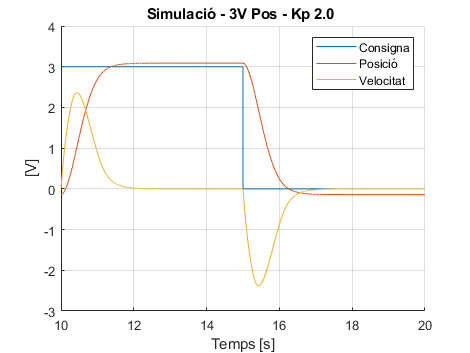

Tsim = 30;
Tmin = 10;
Tmax = 20;

%out = sim('PlantaTFG.slx', Tsim);
out = sim('PlantaTFG2020a.slx', Tsim);
IndexObj = (Tmin < out.tout) & (out.tout < Tmax);
Consigna = out.Consigna.Data(IndexObj);
Posicio = out.Posicio.Data(IndexObj);
Velocitat = out.Velocitat.Data(IndexObj);
u = out.u.Data(IndexObj);
tout = out.tout(IndexObj);

figure();
hold on;
grid on;
plot(tout, Consigna);
plot(tout, Posicio);
plot(tout, Velocitat);
ylabel('[V]');
xlabel('Temps [s]');
legend('Consigna', 'Posició', 'Velocitat');
titleString = ['Simulació - ', entradaString]; %'Simulació - Entrada - Controlador'
if (Kp ~= 0)
    titleString = [titleString, sprintf('Kp %.1f ', Kp)];
elseif (Ki ~= 0) 
    titleString = [titleString, sprintf('Ki %.1f ', Ki)];
elseif (Kd ~= 0) 
    titleString = [titleString, sprintf('Kd %.1f', Kd)];
end
title(titleString);
exportgraphics(gcf, [titleString, '.png']);

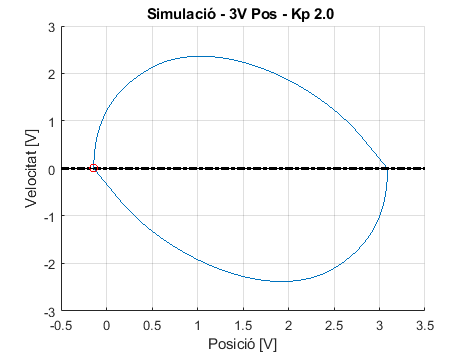


figure();
hold on;
grid on;
plot3(Posicio, Velocitat, u);
plot3(Posicio(1), Velocitat(1), u(1),'ro');
extremFill = xlim;
fill3([extremFill(2), extremFill(2), extremFill(1), extremFill(1)], [0, 0, 0, 0], [Vdi, Vds, Vds, Vdi], 'r');
alpha(0.3);
plot3(extremFill, [0 0], [0 0], 'k-.', 'LineWidth', 2);
xlabel('Posició [V]')
ylabel('Velocitat [V]')
zlabel('u [V]')
title(titleString);